clear
set(0, 'DefaultAxesFontName', 'Times');
data=load("Measurements\ImplementedFilter.csv")

data = 1.0e+05 *

    0.9488   -0.0000    0.0000   -0.0001    0.0000   -0.0000         0    0.0000   -0.0000
    0.9495   -0.0000   -0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9503         0    0.0000   -0.0001    0.0000   -0.0000         0    0.0000   -0.0000
    0.9511   -0.0000   -0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9518         0    0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9526   -0.0000         0   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9534   -0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9542   -0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9549   -0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.9557   -0.0000    0.0000   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000


Time=(data(:,1)-data(1,1))/1000; %Tid nulstiller og omregner til sekunder. 
Acc=data(:,2:4); %Omregning fra g til m/s^2 for acceleration. 
D_object=data(:,5);  %Afstanden til objektet og omregne til meter

Ardunio_Estimation=data(:,6:end); 


%Model representation: 
phi=0.99;
Ts=0.077; 
Phi= [phi,0,0,0;Ts,1,0,0;0,Ts,1,0;0,0,0,1]

Phi =     0.9900         0         0         0
    0.0770    1.0000         0         0
         0    0.0770    1.0000         0
         0         0         0    1.0000


%Phi=Phi(1:3,1:3)
H= [1,0,0,1;0,0,1,0];
%H=H(:,1:3)
%Measurement noise
Ra=0.17^2;  
Rp=0.7/(100^2);

R=[Ra,0;0,Rp]

R =     0.0289         0
         0    0.0001




Q_a=0.0419^2;  
Q_b=0.002

Q_b = 0.0020

Q=[Q_a,0,0,0;0,0,0,0;0,0,0,0;0,0,0,Q_b]

Q =     0.0018         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0    0.0020


%Q=Q(1:3,1:3)





%Making a few definition  (of zeros) before the for loop for the Kalman filter. 
N_samples=length(data);
N_states=size(Phi,1);
N_outputs=size(H,1);

%Kalman gian: 
K=zeros(N_states,N_outputs,N_samples); 
% Estimation error: 
y_error=zeros(N_outputs,N_samples); 

yp= zeros(N_outputs,N_samples); % prediction for output p=prediction thereby k|k-1 


xe= zeros(N_states,N_samples); %estimation of state E for estimation thereby k|k
xp= zeros(N_states,N_samples); %prediction for states, p=prediction. thereby k|k-1

%Making a matrix with the measured data,

measured=[Acc(:,1)';D_object'];

% Initialising
%Position=distance to object therefore takning the first one out. 
x0=[0;0;D_object(1,1);0]; 
%x0=x0(1:3,1)
P0= eye(N_states)*0.1; 

P0=zeros(4,4)

P0 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



%Initlaxation values for the Kalman filter
xp(:,1)= x0; 
Pp= P0;
% Kalman filter. 
for i= 1:N_samples
  % Measurement update
  %Predite the output
  yp(:,i)= H*xp(:,i); 
  
  %Estimation error: %Update when data is avable
  y_error=measured(:,i)-yp(:,i); 
  %Kalman gain:
  K(:,:,i)= Pp*H'*inv((H*Pp*H'+R)); 
  %estimation of x: 
  xe(:,i)= xp(:,i)+K(:,:,i)*(y_error); 
  %Covaraince of error estimation: 
  Pe= (eye(N_states)-K(:,:,i)*H)*Pp*(eye(N_states)-K(:,:,i)*H)'+K(:,:,i)*R*K(:,:,i)';

  % Time update
  xp(:,i+1)= Phi*xe(:,i);
  Pp= Phi*Pe*Phi'+Q;
end


%Plotter alle estimationer af states altså x(k|k), for ens kalman filter: 
f=figure(29)

f =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 1000 1000 733.6667]
       Units: 'pixels'

  Show all properties


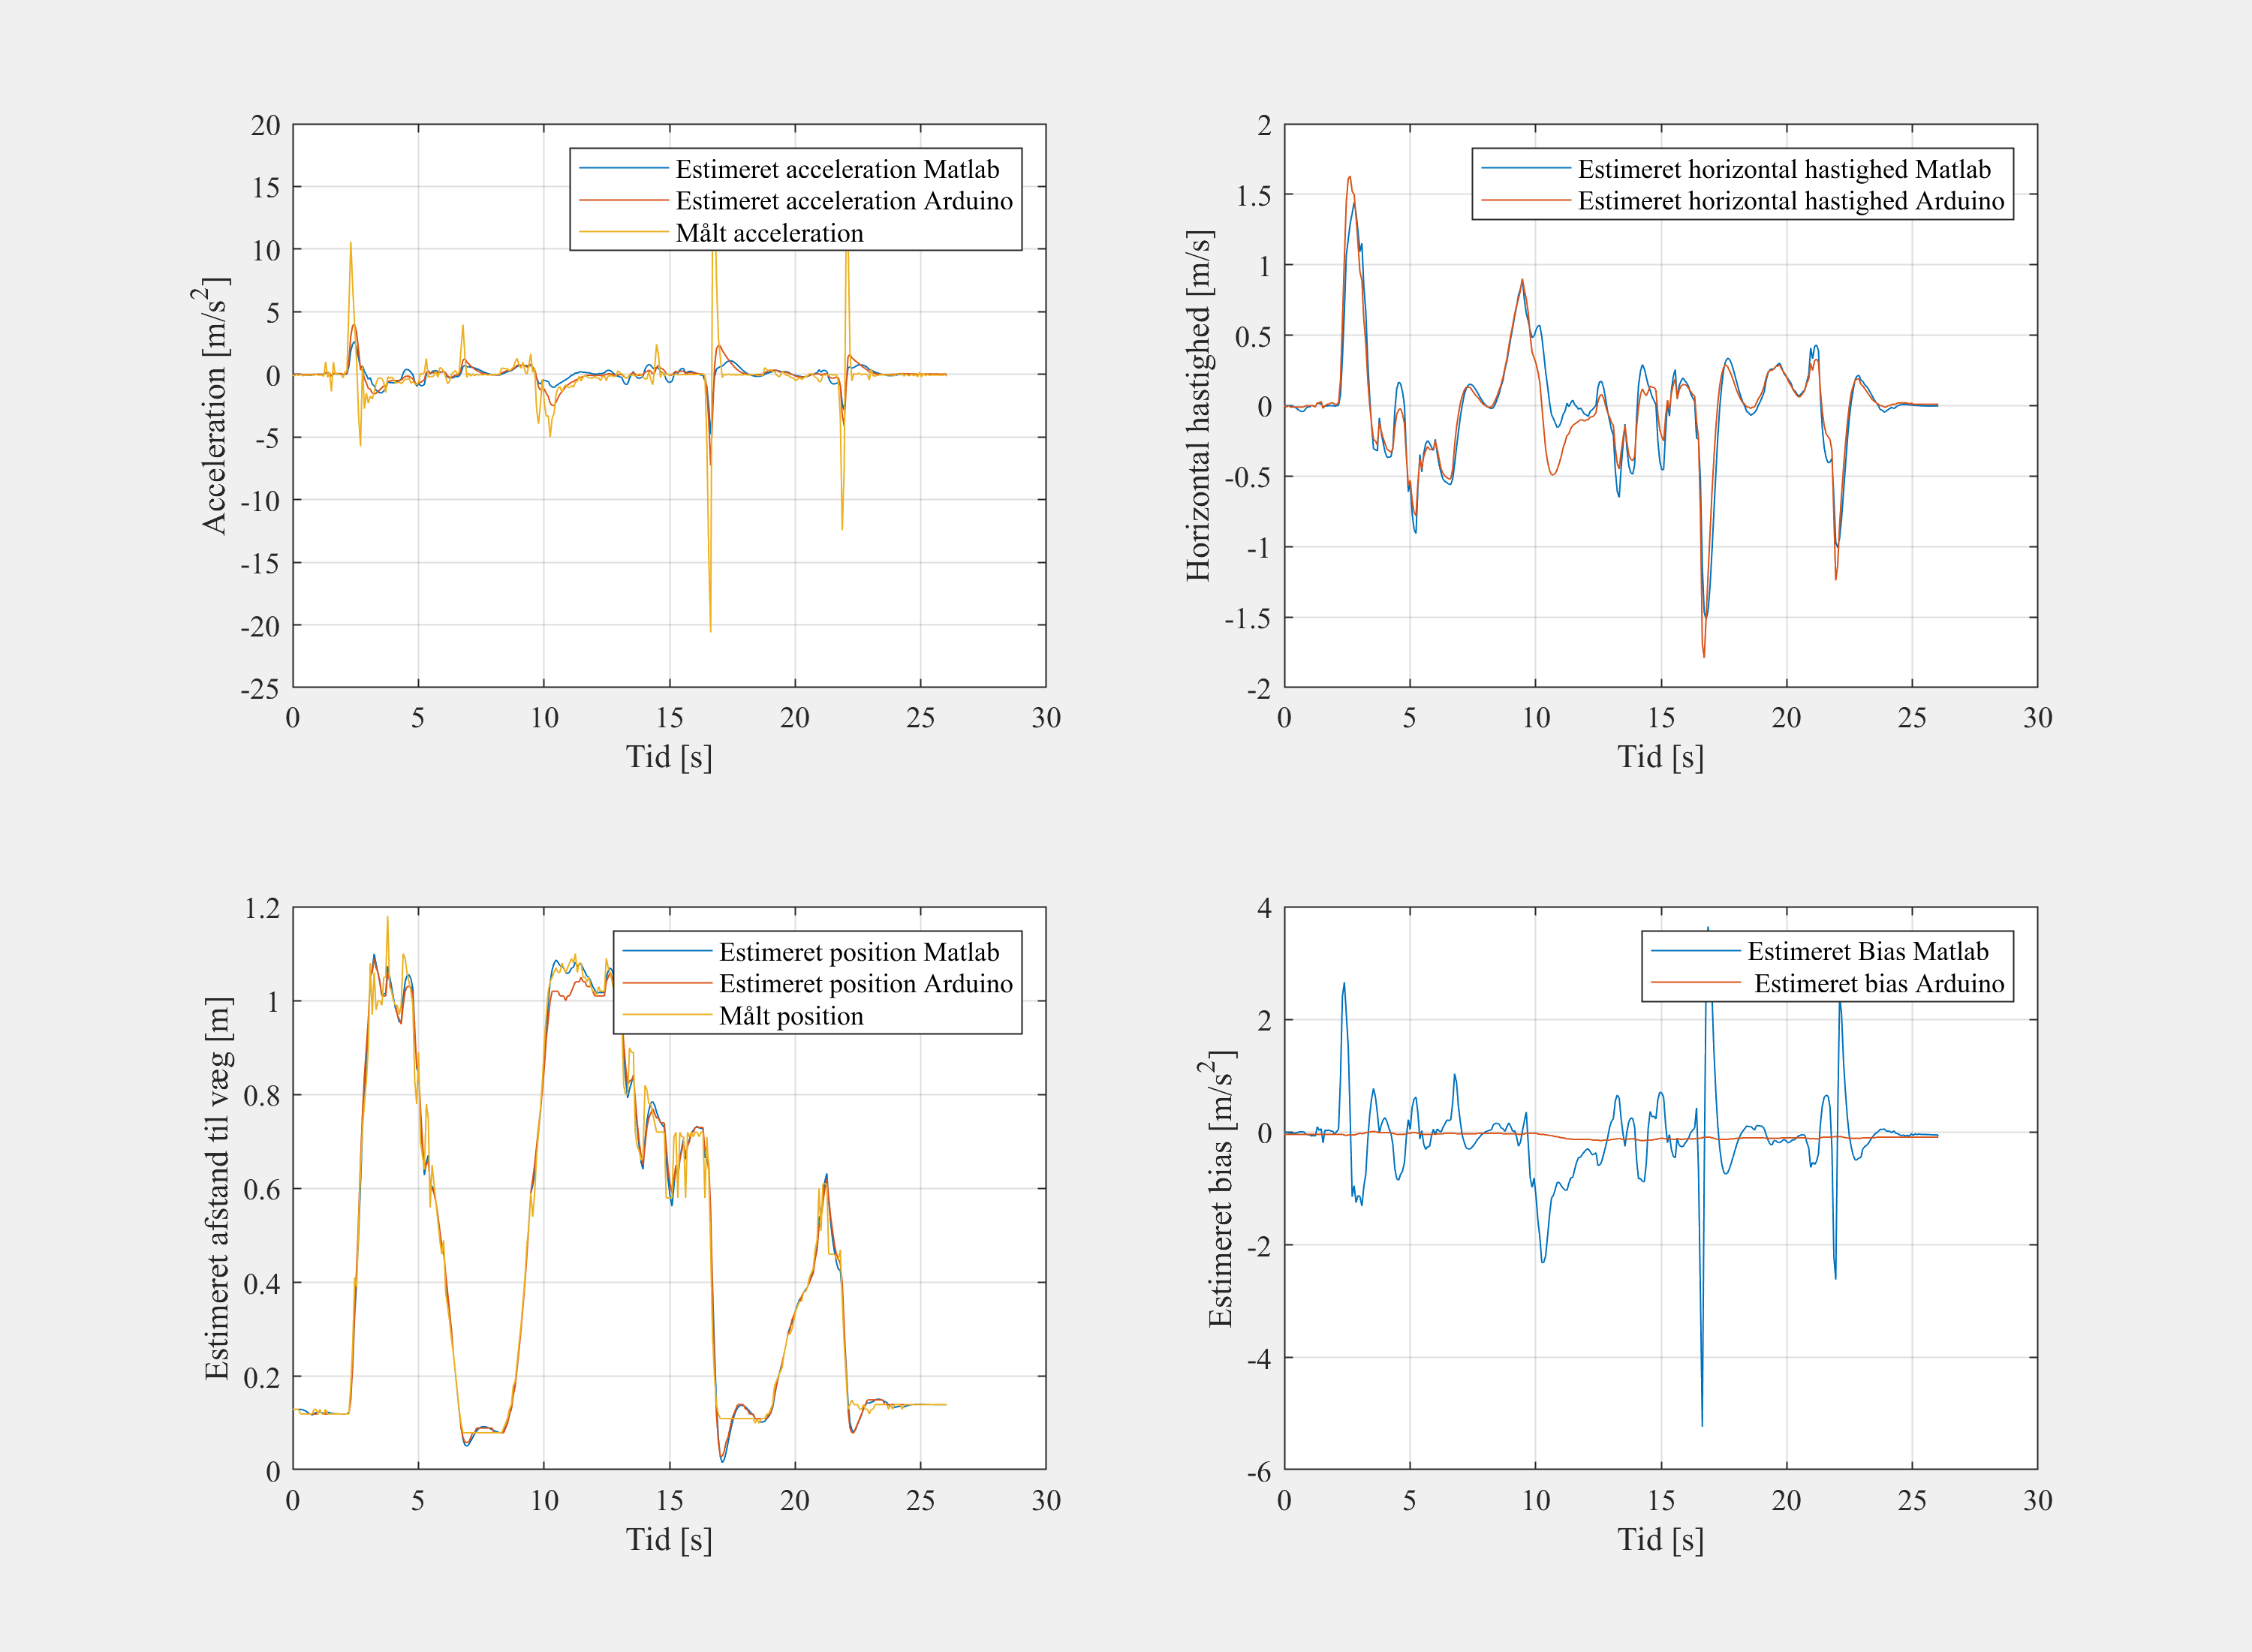

f.Position = [1000 1000 1000 1000];

set(gcf,'Visible','on')
subplot(2,2,1)
plot(Time,xe(1,:))
hold on 
plot(Time,Ardunio_Estimation(:,1))
plot(Time,Acc(:,1))
hold off 
legend("Estimeret acceleration Matlab","Estimeret acceleration Arduino","Målt acceleration")

xlabel("Tid [s]")
ylabel("Acceleration [m/s^2]")
grid 
subplot(2,2,2)
plot(Time,xe(2,:))
hold on 
plot(Time,Ardunio_Estimation(:,2))
hold off
xlabel("Tid [s]")
ylabel("Horizontal hastighed [m/s]")
grid
legend("Estimeret horizontal hastighed Matlab","Estimeret horizontal hastighed Arduino")
subplot(2,2,3)
plot(Time,xe(3,:))
hold on 
plot(Time,Ardunio_Estimation(:,3))
plot(Time,D_object)
hold off
xlabel("Tid [s]")
ylabel("Estimeret afstand til væg [m]")
legend("Estimeret position Matlab","Estimeret position Arduino","Målt position")
grid 
subplot(2,2,4)
plot(Time,xe(4,:))
hold on 
plot(Time,Ardunio_Estimation(:,4))
hold off
xlabel("Tid [s]")
ylabel("Estimeret bias [m/s^2]")
legend("Estimeret Bias Matlab"," Estimeret bias Arduino")
grid

exportgraphics(f,"Kalman_filter_sammenligne.pdf")


